# **Лабораторная работа №1**

# **Синтез и фильтрация ШПС-сигналов типа M - последовательностей и кодов Уолша - Адамара**

**Выполнил: Голев Андрей Дмитриевич, ИВТ-32.**

**Преподаватель: Лавриненко Александр Дмитриевич.**

# Часть №1

# Cинтез и фильтрация M-последовательностей

## Задача №1

Реализовать функцию **Mfun( A, C )**, представляющий собой цифровой автомат генерации **M - последовательности, **где 

- **A** - фаза;

- **C** - характеристический многочлен последовательности.

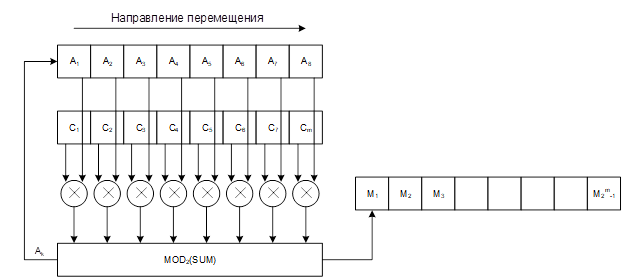

Сформировать две последовательности согласно своему варианту.

Полученные **M - последовательности **следует привести к виду [1; -1], проведя замену в исходных последовательностях:

- **0** на 1;

- **1** на -1.

clear; clc; close all;

% Вариант №6 

A   = [ 1 0 0 0 0 0 0 1 1 0 ];
C_1 = [ 0 0 1 1 1 0 0 1 1 1 ];
C_2 = [ 0 0 1 1 1 1 0 0 1 1 ];

M_1 = Mfun( A, C_1 );
M_2 = Mfun( A, C_2 );

M_1 = SubM( M_1 );
M_2 = SubM( M_2 );

Изобразить полученные М-последовательности на отдельных графиках.

subplot( 3, 1, 1 )

plot( linspace( 1, length( M_1 ), length( M_1 ) ), M_1 )

title( "Последовательность M_1" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

subplot( 3, 1, 2 )

plot( linspace( 1, length( M_2 ), length( M_2 ) ), M_2 )

title( "Последовательность M_2" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

## Задача №2

Сформировать сумму M-последовательностей $M_{\textrm{сум}} =M_1 +M_2$, где $M_2$ взят со сдвигом и инверсией.

Сдвиг взять равным 100 + номер по списку в группе  * 10 <= length(M) / 2 

M_sum = [ M_1, zeros( 1, 160 ) ] + [ zeros(1, 160 ), M_2 * ( -1 ) ];

subplot( 3, 1, 3 )

plot( linspace( 1, length( M_sum ), length( M_sum ) ), M_sum )

title( "Последовательность M_{сум}" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

## Задача №3

Запрограммировать функцию **my_sf( A, B )**, реализующую согласованный фильтр для фильтрации **M-последовательностей** и построения **автокорреляционных** и **взаимно-корреляционных** функций, где

- **A** - сигнал

- **B** - опорная функция.

Построить **АКФ** для $M_1$.

AKF = my_sf( M_1, M_1 );

figure

subplot( 4, 2, 1 )
plot( linspace( 1, length( AKF ), length( AKF ) ), AKF )

title( "Автокорреляция для M_1" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

Построить **ВКФ** для $M_2$.

VKF = my_sf( M_2, M_1 );

subplot( 4, 2, 3 )
plot( linspace( 1, length( VKF ), length( VKF ) ), VKF )

title( "Взаимная корреляция для M_1 и M_2" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

Из $M_{\textrm{сум}}$ отфильтровать $M_{1\;} \ldotp$

Filtered_signal_1 = my_sf( M_sum, M_1 );

subplot( 4, 2, 5 )
plot( linspace( 1, length( Filtered_signal_1 ), length( Filtered_signal_1 ) ), Filtered_signal_1 )

title( "Отфильтрованная последовательность M_1" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

Из $M_{\textrm{сум}}$ отфильтровать $M_{2\;} \ldotp$

Filtered_signal_2 = my_sf( M_sum, M_2 );

subplot( 4, 2, 7 )
plot( linspace( 1, length( Filtered_signal_2 ), length( Filtered_signal_2 ) ), Filtered_signal_2 )

title( "Отфильтрованная последовательность M_2" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

Воспользуемся функцией xcorr

AKF = xcorr( M_1, M_1 );

subplot( 4, 2, 2 )
plot( linspace( 1, length( AKF ), length( AKF ) ), AKF )

title( "Автокорреляция для M_1 с помощью xcorr" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

VKF = xcorr( M_2, M_1 );

subplot(4,2,4)
plot( linspace( 1, length( VKF ), length( VKF ) ), VKF )

title( "Взаимная корреляция для M_1 и M_2 с помощью xcorr" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

Filtered_signal_1 = xcorr( M_sum, M_1 );

subplot( 4, 2, 6 )
plot( linspace( 1, length( Filtered_signal_1 ), length( Filtered_signal_1 ) ), Filtered_signal_1 )

title( "Отфильтрованная с помощью xcorr последовательность M_1" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

Filtered_signal_2 = xcorr( M_sum, M_2 );

subplot( 4, 2, 8 )
plot( linspace( 1, length( Filtered_signal_2 ), length( Filtered_signal_2 ) ), Filtered_signal_2 )

title( "Отфильтрованная с помощью xcorr последовательность M_2" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

## Задача №4

Сформировать шум с помощью функции rand. В качестве амплитуды шума взять свой номер по списку в группе. Длина сформированного шума должна соответствовать длине M-последовательности.

Сформируем шум

Noise = 6 - 2 * 6 * rand(1, length( M_1 ) );

Сложим первую последовательность с шумом

M_3 = M_1 + Noise;

Изобразим

figure

subplot( 3, 1, 1 )

plot( linspace( 1, length( M_3 ), length( M_3 ) ), M_3 )

title( "Последовательность M_1 с шумом" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on


Отфильтруем последовательность $M_1$

Filtered_signal_3 = my_sf( M_3, M_1 );

subplot( 3, 1, 2)
plot( linspace( 1, length( Filtered_signal_3 ), length( Filtered_signal_3 ) ), Filtered_signal_3 )

title( "Отфильтрованная последовательность M_1 без шума" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

Изобразим последовательность в логарифмическом масштабе

dB = 20 * log10( abs( Filtered_signal_3 ./ max( Filtered_signal_3 ) ) );

subplot(3,1,3)
plot( linspace( 1, length( dB ), length( dB ) ), dB )

title( "Отфильтрованная последовательность в логарифмическом масштабе" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

# Часть №2

# Синтез и фильтрация кодов Уолша-Адамара

## Задача №1

Запрограммировать функцию **Wfun( data, r )**, реализующую цифровой автомат генерации кодов Уолша-Адамара, где 

- **data** - число, для которого генерируется код Уолша-Адамара;

- **r** - требуемая разрядность для числа data.

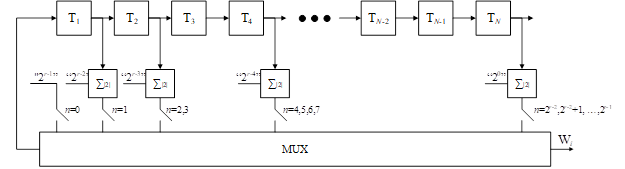

*Если разрядность кодируемого числа r, то длина кода Уолша-Адамара этого числа будет равна *$2^{r-1}$.

Синтезировать коды $W_1$ и $W_2$ с помощью функции **Wfun **и сформировать сумму кодов $W_{\textrm{Сум}} =W_1 +W_2$.

clear; clc; close all;

% Вариант 6

data_1 = 6;
data_2 = 356;
r = 10;

W_1 = Wfun( data_1, r );
W_2 = Wfun( data_2, r );

W_1 = SubM( W_1 );
W_2 = SubM( W_2 );

## Задача №2

Запрограммировать функцию **Bpfun( w, r )**, реализующую быстрое преобразование Уолша - Адамара, где

- **w** - код Уолша - Адамара,

- **r **- разрядность числа, представленного кодом Уолша - Адамара.

Вычислить быстрое преобразование Уолша - Адамара для суммы кодов $W_{\mathrm{сум}}$.

% Something